**Create a time vector from 0 to 63 seconds**

N = 64;
dt = 1;  %sample period
t = (0:N-1)'*dt;

**1) **

- **Form a cosine time series (x) with amplitude = 3 m and period = 16 sec.  **

- **Compute the Fourier transform (X) of x**

- **Plot x and Fourier coefficients (real(X)/N and imag(X)/N)**

A = 3;
T = 16;
x = A*cos(2*pi*t/T);

Fourier transform and shift to -f -> f

X = fft(x);
X = fftshift(X);
fN = 1/(2*dt);
df = 1/(N*dt);
f = (-fN:df:fN-df)';

Plot time series, real and imaginary Fourier coefficients

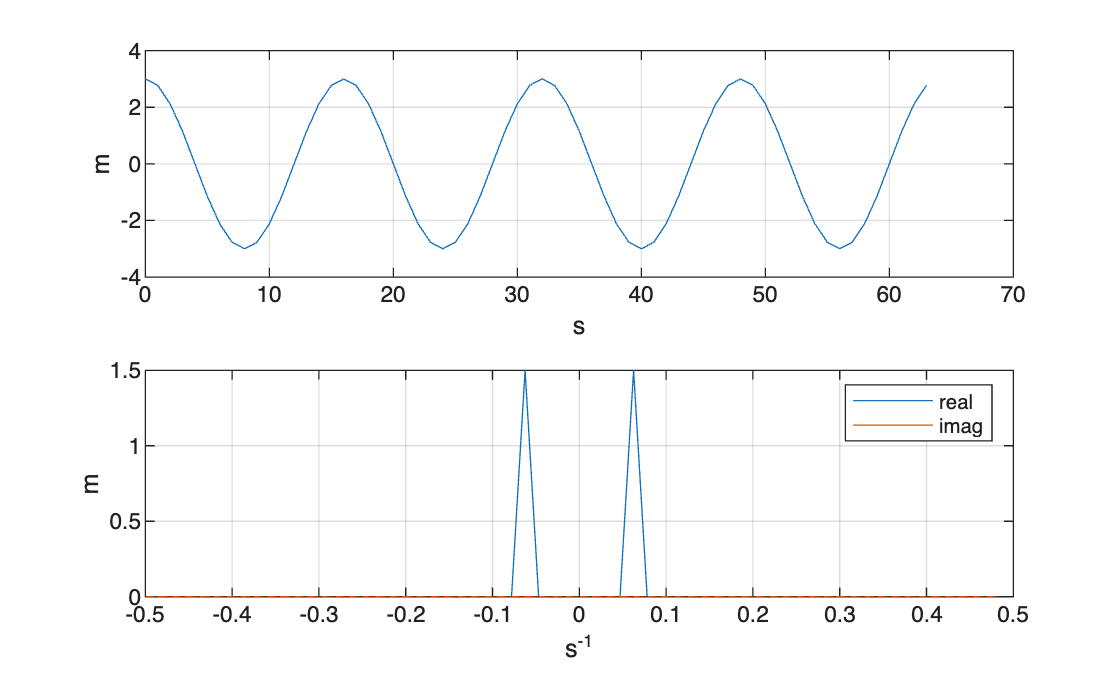

subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**2) Repeat 1) adding a constant value of 1m to x**

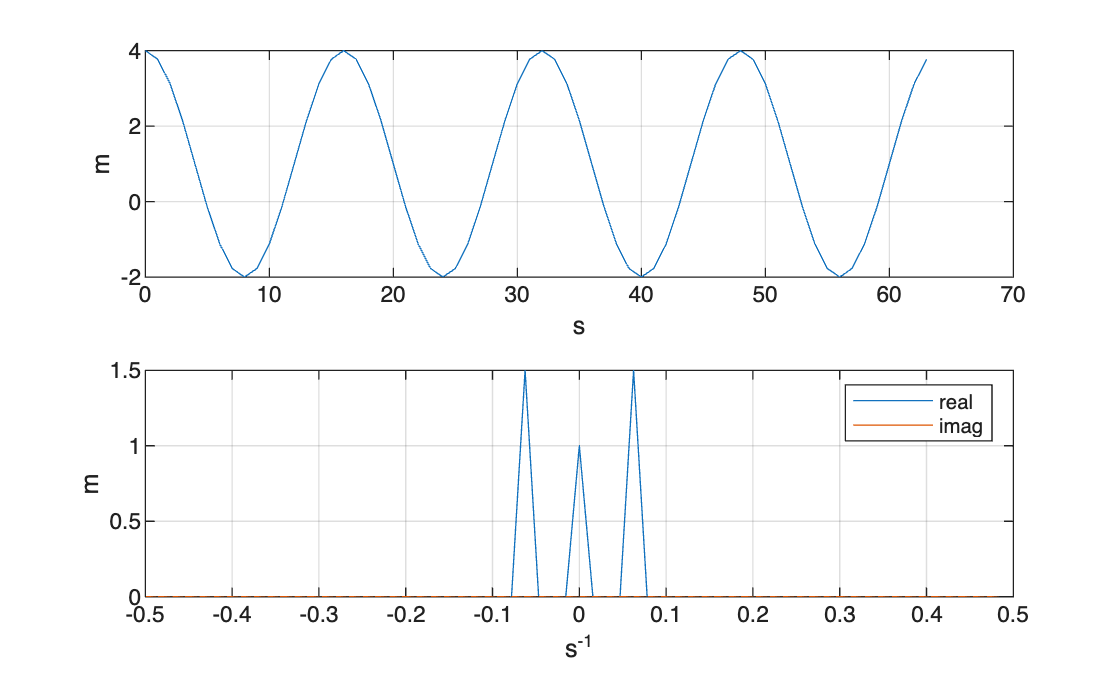

A = 3;
T = 16;
x = A*cos(2*pi*t/T) + 1;
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**3) Repeat 1) replacing the cosine with a sine**

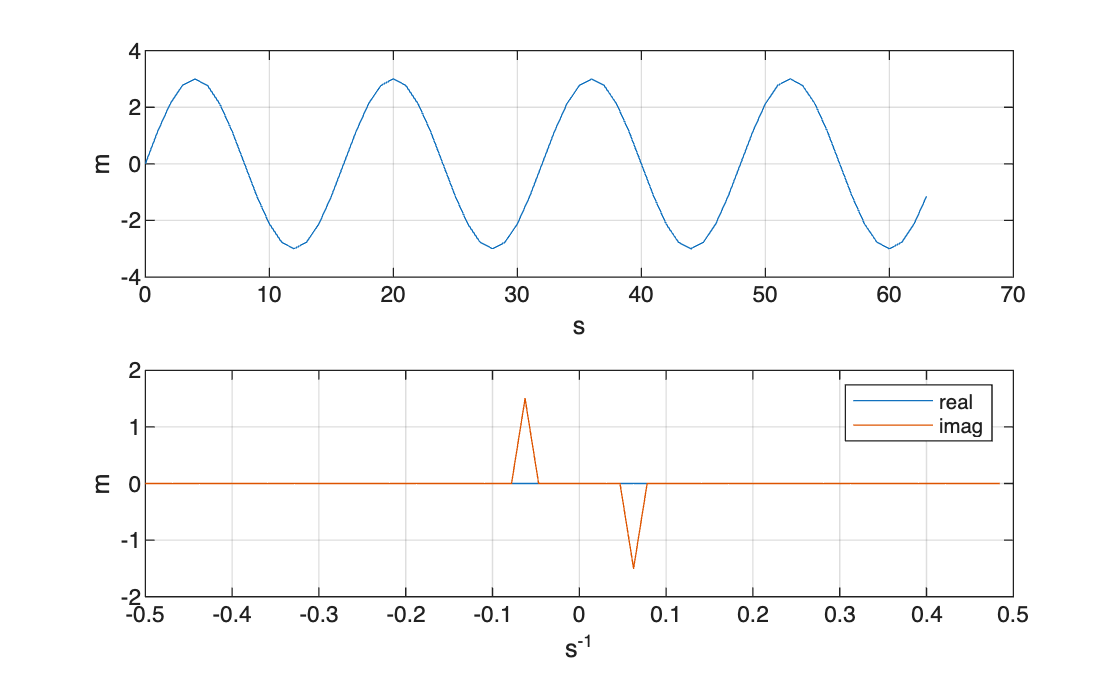

A = 3;
T = 16;
x = A*sin(2*pi*t/T);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**4) Repeat 1) adding a sine with amplitude = 2 and period = 16 sec**

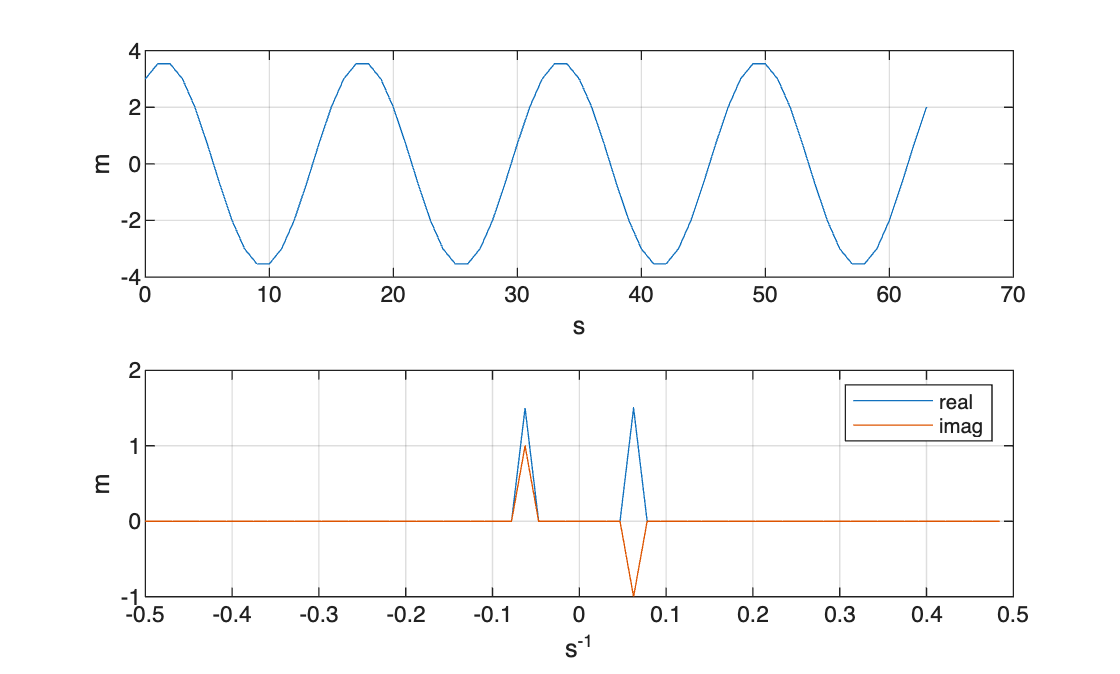

A = 3;
B = 2;
T = 16;
x = A*cos(2*pi*t/T) + B*sin(2*pi*t/T);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**5) Repeat 1) adding a sine with amplitude = -1m and period = 8 sec**

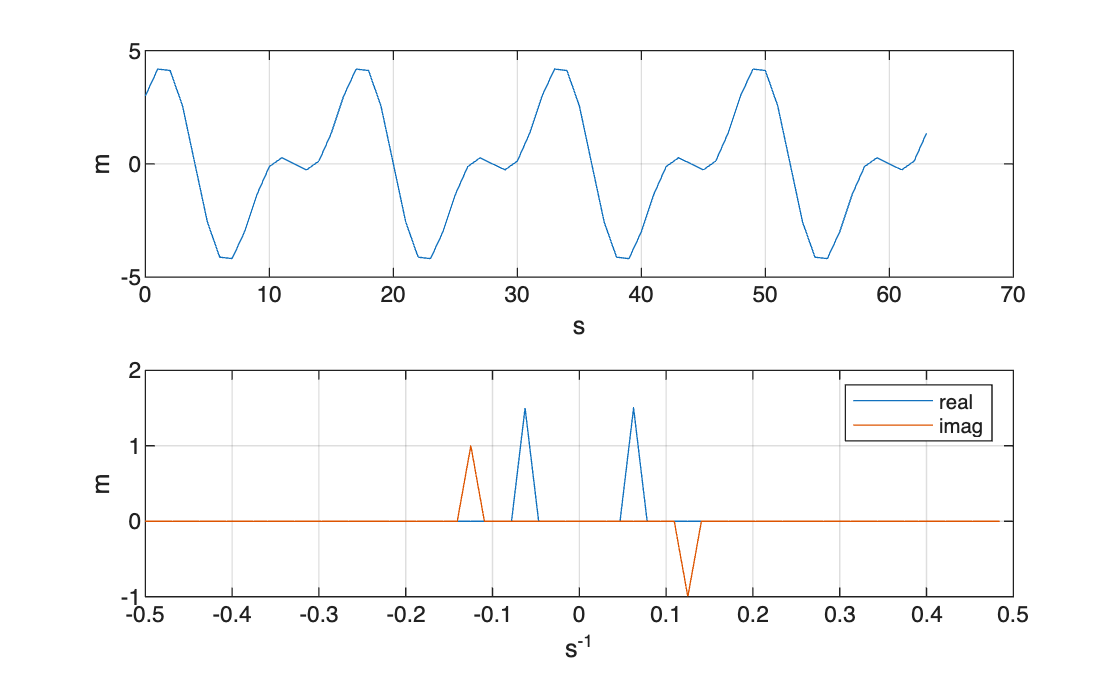

A = 3;
B = 2;
Ta = 16;
Tb = 8;
x = A*cos(2*pi*t/Ta) + B*sin(2*pi*t/Tb);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**6)  Repeat 1) with amplitude = 3 and period = 2 sec (Nyquist)**

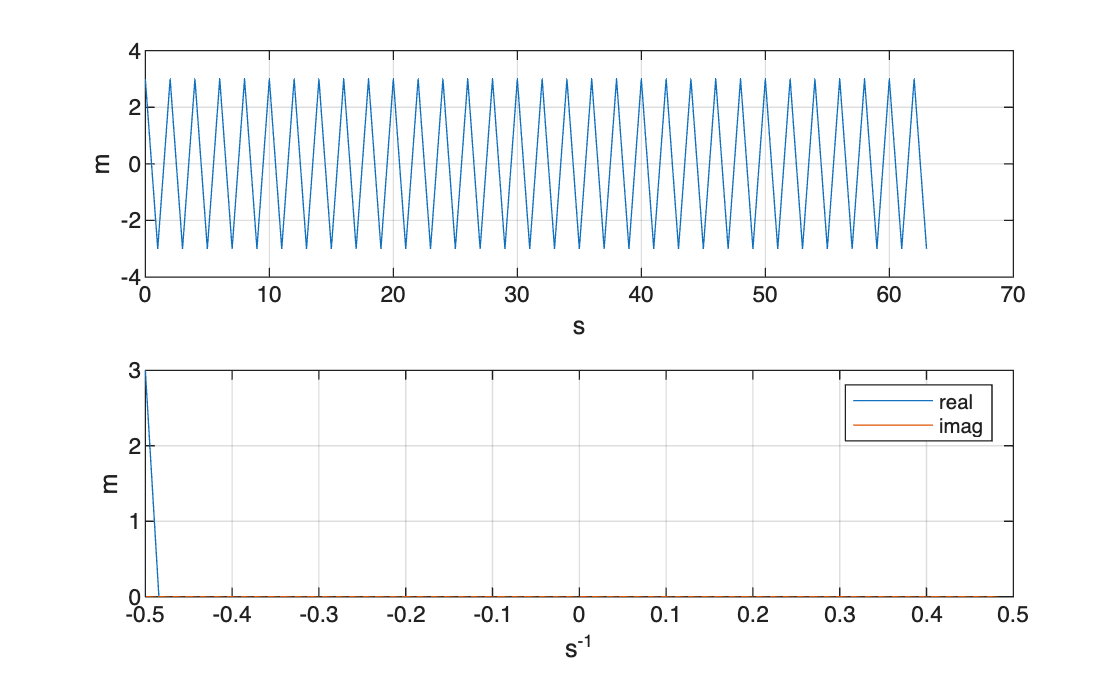

A = 3;
T = 2;
x = A*cos(2*pi*t/T);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**7) Repeat 1) with amplitude = 3 and period = 14 sec.  **

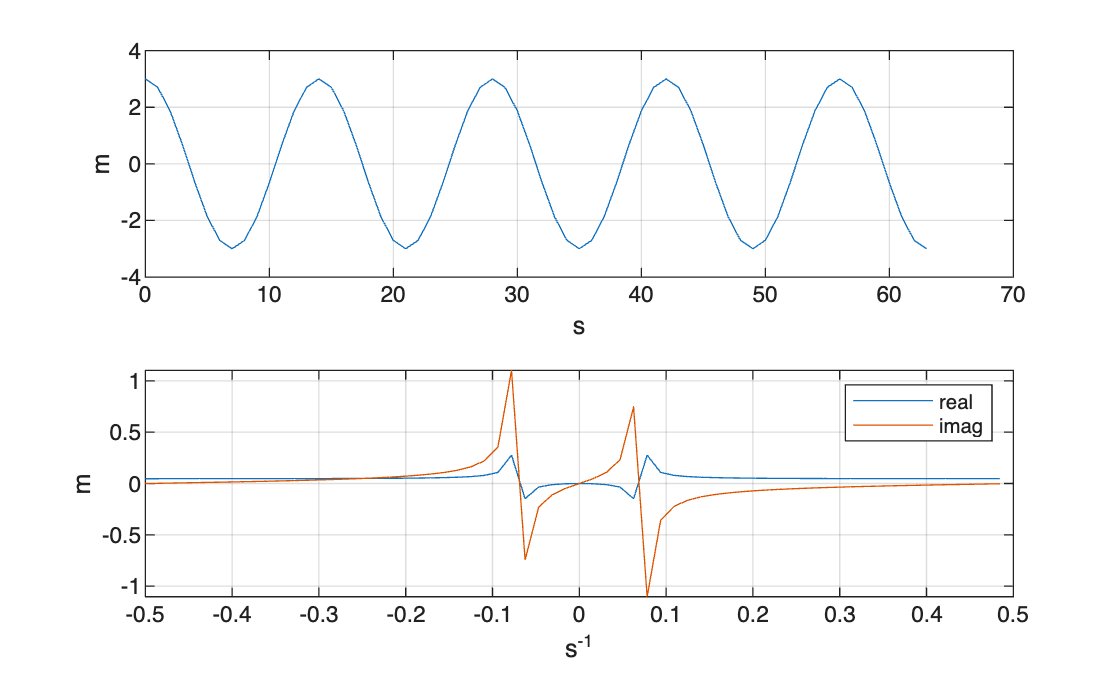

A = 3;
T = 14;
x = A*cos(2*pi*t/T);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on

**8) **

- **Form a time series (x) that is all zeros with a single spike of amplitude = 1m at t = 32 s.  **

- **Compute the Fourier transform (X) of x**

- **Plot x and Fourier coefficients (real(X)/N, imag(X)/N, abs(X)/N)**

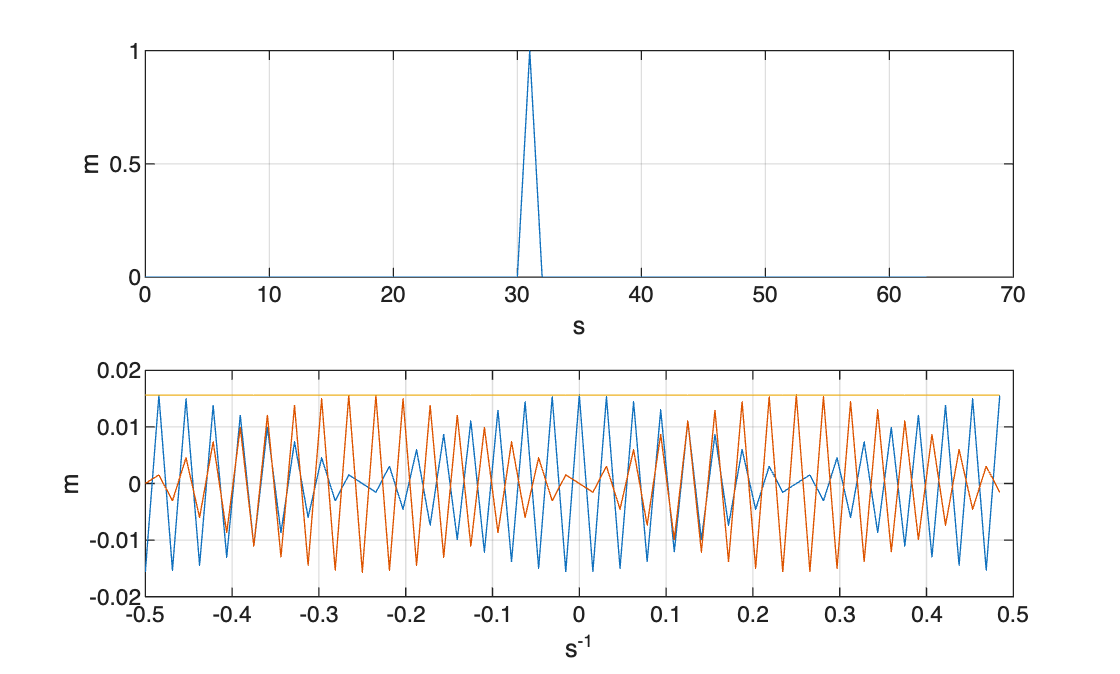

x = zeros(64,1);
x(32) = 1;
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N,f,abs(X)/N)
xlabel('s^{-1}')
ylabel('m')
grid on

**9) **

- **Form a 64 pt random time series (x) using "rand"**

- **Remove the mean from x **

- **Compute the Fourier transform (X) of x**

- **Plot x and Fourier coefficients (real(X)/N, imag(X)/N, abs(X)/N)**

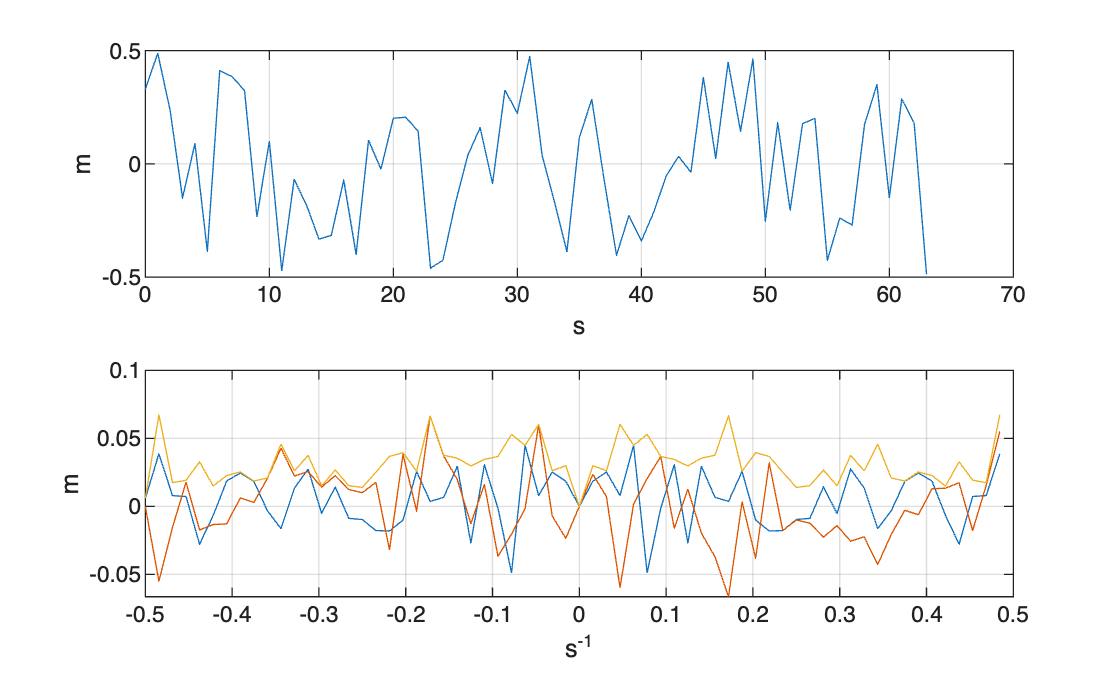

x = rand(64,1);
x = detrend(x,0);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N,f,abs(X)/N)
xlabel('s^{-1}')
ylabel('m')
grid on

**10) **

- **Form a 64 pt time series (x) that is a straight line trend from 0 to 3m**

- **Remove the mean from x**

- **Compute the Fourier transform (X) of x**

- **Plot x and Fourier coefficients (real(X)/N, imag(X)/N, abs(X)/N)**

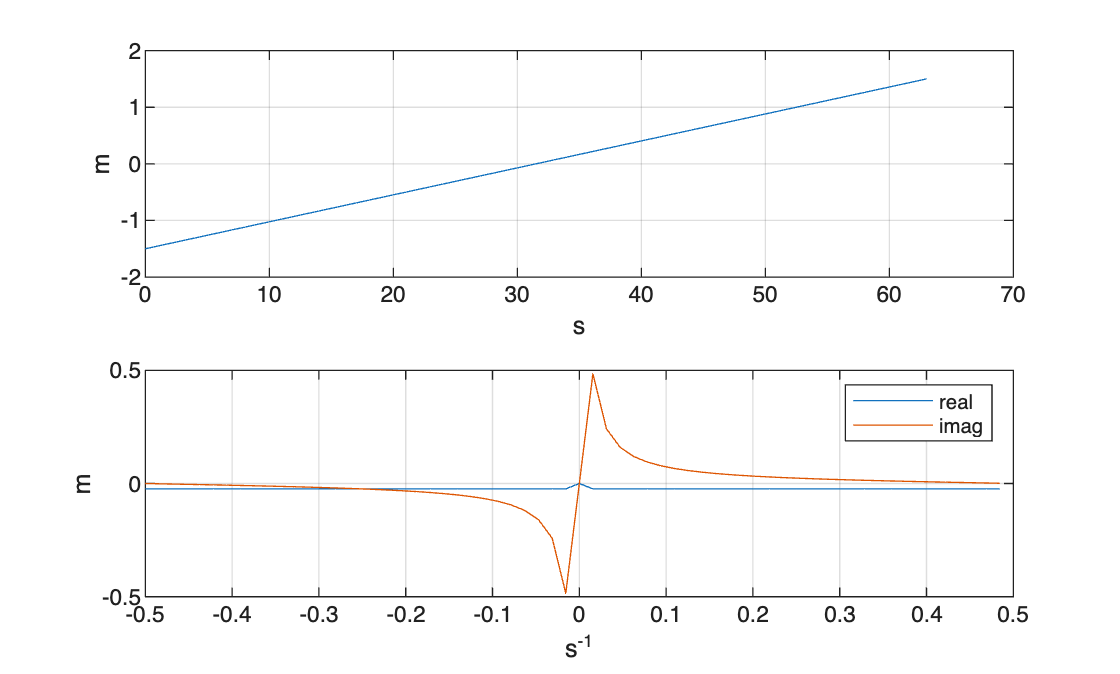

x = linspace(0,3,64);
x = detrend(x,0);
X = fft(x);
X = fftshift(X);
subplot(2,1,1)
plot(t,x)
xlabel('s')
ylabel('m')
grid on
subplot(2,1,2)
plot(f,real(X)/N,f,imag(X)/N)
legend('real','imag')
xlabel('s^{-1}')
ylabel('m')
grid on